## Add paths

clearvars
close all
addpath(fullfile('.','SINDy'));
addpath(fullfile('.','Learn++NSE'));
addpath(fullfile('.','ConceptDriftData'));
addpath(genpath(fullfile('.','advlearn')));

## paths needed for utilizing chris's library, add the paths for your system and restart matlab if matlab cant find them

p = py.sys.path;
insert(p,int32(0), pwd + "\advlearn\")
insert(p,int32(0), pwd + "\advlearn\advlearn\attacks\poison\")
insert(p,int32(0), pwd + "\advlearn\advlearn\attacks\")

## Load the Dataset

%T = 200;  % number of time stamps
%N = 100;  % number of data points at each time
%[data_train, labels_train,data_test,labels_test] = ConceptDriftData('sea', T, N);
dataset = "X2CDT";
x = load("Synthetic Datasets\" + dataset + ".mat");
data_train = x.(dataset).dataTrain;
data_test = x.(dataset).dataTest;
labels_test = x.(dataset).labelsTest;
labels_train = x.(dataset).labelsTrain;
T = length(data_train);
for t = 1:T
  data_train{t} = data_train{t};
  labels_train{t} = labels_train{t};
  data_test{t} = data_test{t};
  labels_test{t} = labels_test{t};
end

### Extracts all the data information

numTimeSteps = length(data_train);
[numObs, numDims] = size(data_train{1});
numClasses = numel(unique(labels_train{1}));
classLabelsIdxs = cell(numTimeSteps,numClasses);
classData = cell(numTimeSteps,numClasses);
classMeans = cell(numTimeSteps,numClasses);
classVariances = cell(numTimeSteps,numClasses);
numObsPerClass = cell(numTimeSteps,numClasses);
for iClass = 1:numClasses
	[classLabelsIdxs(:,iClass)] = cellfun(@(x) eq(x,iClass),labels_train',...
                              'UniformOutput',false); % Get indexes for data points of classNumber at each time step
	[classData(:,iClass)] = cellfun(@(a,b) a(b,:),data_train',classLabelsIdxs(:,iClass),...
                        'UniformOutput',false); % Now extract the class data using logical indexing at each time step 
	[classMeans(:,iClass)] = cellfun(@(x) mean(x),classData(:,iClass),...
                           'UniformOutput',false); % Calculate the means at every time step
	[classVariances(:,iClass)] = cellfun(@(x) cov(x),classData(:,iClass),...
                               'UniformOutput',false); % Calculate the covariance at every time step
    [numObsPerClass(:,iClass)] = cellfun(@(x) size(x,1), classData(:,iClass),...
                               'UniformOutput',false);
end

## nseData is structure array (timestep), stores training data, test data, and labels to feed into Learn++.NSE

nseData = repmat(struct("dataTrain",zeros(numObs,numDims),...
                        "dataTest",zeros(numObs,numDims),...
                        "labelsTrain",zeros(numObs,1),...
                        "labelsTest",zeros(numObs,1)),1,numTimeSteps);
[nseData.dataTrain] = data_train{:};
[nseData.dataTest] = data_test{:};
[nseData.labelsTrain] = labels_train{:};
[nseData.labelsTest] = labels_test{:};

### classInfo is structure array (timestep,class), stores data, means, covariances, number of observations, and indexes of classes within data matrix

classInfo = repmat(struct("mu",zeros(1,numDims),...
                               "sigma",zeros(numDims,numDims),...
                               "data",zeros(numObs,numDims),...
                               "numObs",0,...
                               "idx",false(numObs,1)),numTimeSteps,numClasses);
[classInfo(:,:).mu] = classMeans{:,:};
[classInfo(:,:).sigma] = classVariances{:,:};
[classInfo(:,:).data] = classData{:,:};
[classInfo(:,:).numObs] = numObsPerClass{:,:};
[classInfo(:,:).idx] = classLabelsIdxs{:,:};

## SINDyData is structure array (timestep,class), stores the means and sigma to feed into SINDy at each time step

SINDyData = repmat(struct("mu",0,"sigma",0),numTimeSteps,numClasses);
for iClass = 1:numClasses
    for iTStep = 2:numTimeSteps
        SINDyData(iTStep,iClass).mu = vertcat(classInfo(1:iTStep,iClass).mu);
        SINDyData(iTStep,iClass).sigma = classInfo(iTStep-1,iClass).sigma;
    end
end
[SINDyData.latestReset] = deal(1);
clearvars -except numTimeSteps numObs numDims nseData numClasses dataset classInfo SINDyData % clear useless variables to clean up workspace

### SINDyResults is a structure array (timestep,class), stores the predicted mean and table of learned functions 

SINDyResults = repmat(struct("prediction",0,"learnedFunctions",0),numTimeSteps,numClasses);

## Classifier parameters

model.type = 'SVM';          % base classifier
model.kernel = 'Linear';
net.a = .5;                   % slope parameter to a sigmoid
net.b = 10;                   % cutoff parameter to a sigmoid
net.threshold = 0.01;         % how small is too small for error
net.mclass = 2;               % number of classes in the prediciton problem
net.base_classifier = model;  % set the base classifier in the net struct
net.initialized = true;
net.classifiers = {};   % classifiers
net.w = [];             % weights 
net.initialized = false;% set to false
net.t = 1;              % track the time of learning
net.classifierweigths = {};               % array of classifier weights
net.type = 'learn++.nse';

## Create a SINDy models. One per class

StdevThresh = 1;
for iClass = numClasses:-1:1
    SINDyArray(numTimeSteps,numClasses) = SINDy(); % SINDy Object ... type help SINDy for list of what each parameter does
end
[SINDyArray.lambda] = deal(8e-3);
[SINDyArray.polyOrder] = deal(1);
[SINDyArray.useSine] = deal(0);
[SINDyArray.sineMultiplier] = deal(10);
[SINDyArray.useExp] = deal(0);
[SINDyArray.expMultiplier] = deal(10);
[SINDyArray.useCustomPoolData] = deal(1);
[SINDyArray.nonDynamical] = deal(0);
% TVRegDiff parameters for SINDy 
[SINDyArray.useTVRegDiff] = deal(0);
[SINDyArray.iter] = deal(10); 
[SINDyArray.alph] = deal(0.00002);
[SINDyArray.ep] = deal(1e12);
[SINDyArray.scale] = deal("small");
[SINDyArray.plotflag] = deal(0);
[SINDyArray.diagflag] = deal(0);

## SVMAttack Parameters

Setup Boundary Regions need to set this up for any dataset

atkSet.step_size = 5;
atkSet.timeToAttack = 3;
atkSet.max_steps = 100;
atkSet.c = 1;
atkSet.kernel = 'linear';
atkSet.degree = 3;
atkSet.coef0 = 1;
atkSet.gamma = 'auto';
atkSet.numAtkPts = 40;
% Mesh and step is for creating boundary of attack
% variables to hold attack points and generated data sets
genDistr = repmat(struct("data",zeros(numObs,numDims),"labels",zeros(numObs,1)),1,numTimeSteps);
atkData = repmat(struct("points",zeros(atkSet.numAtkPts,numDims),...
                           "labels",zeros(atkSet.numAtkPts,1)),1,numTimeSteps);
[genDistr(1:atkSet.timeToAttack-1).data] = deal(0);
[genDistr(1:atkSet.timeToAttack-1).labels] = deal(0);
[atkData(1:atkSet.timeToAttack-1).points] = deal(0);
[atkData(1:atkSet.timeToAttack-1).labels] = deal(0);
thereIsTimeToAttack = true;

## run learn++.nse, and attack

nseResults = repmat(struct("net",net,...
                              "f_measure",zeros(1,net.mclass),...
                              "g_mean",0,...
                              "recall",zeros(1,net.mclass),...
                              "precision",zeros(1,net.mclass),...
                              "errs_nse",0,...
                              "latestClassifier",0),1,numTimeSteps);
profile on
for iTStep = 1:numTimeSteps
    if (iTStep >= atkSet.timeToAttack-1 && thereIsTimeToAttack) % dont start attacking until timestep before time to attack
        for iClass = 1:numClasses
            [model, SINDyResults(iTStep,iClass).learnedFunctions] = ...
            SINDyArray(iTStep,iClass).buildModel(SINDyData(iTStep,iClass).mu,...
                                                 1,...
                                                 SINDyData(iTStep).latestReset,...
                                                 iTStep,...
                                                 1);
            SINDyResults(iTStep,iClass).prediction = model(end,:);
            % Generate distribution for next time step
            % last row of SINDy.model is the predicted time step
            genDistr(iTStep+1).data(classInfo(iTStep,iClass).idx,:) = ...
                               mvnrnd(SINDyResults(iTStep,iClass).prediction,...
                                      SINDyData(iTStep,iClass).sigma,...
                                      classInfo(iTStep,iClass).numObs);
            genDistr(iTStep+1).labels(classInfo(iTStep,iClass).idx,:) = ...
                          repmat(iClass,classInfo(iTStep,iClass).numObs,1);
        end
    end
    if (iTStep < atkSet.timeToAttack && thereIsTimeToAttack) % perform Learn++.NSE 
        if iTStep == 1
            [nseResults(iTStep).net,...
            nseResults(iTStep).f_measure,...
            nseResults(iTStep).g_mean,...
            nseResults(iTStep).precision,...
            nseResults(iTStep).recall,...
            nseResults(iTStep).errs_nse,...
            nseResults(iTStep).latestClassifier] = learn_nse_for_attacking(nseResults(iTStep).net,...
                                                nseData(iTStep).dataTrain,...
                                                nseData(iTStep).labelsTrain,...
                                                nseData(iTStep).dataTest,...
                                                nseData(iTStep).labelsTest);
        else
            [nseResults(iTStep).net,...
            nseResults(iTStep).f_measure,...
            nseResults(iTStep).g_mean,...
            nseResults(iTStep).precision,...
            nseResults(iTStep).recall,...
            nseResults(iTStep).errs_nse,...
            nseResults(iTStep).latestClassifier] = learn_nse_for_attacking(nseResults(iTStep-1).net,...
                                                nseData(iTStep).dataTrain,...
                                                nseData(iTStep).labelsTrain,...
                                                nseData(iTStep).dataTest,...
                                                nseData(iTStep).labelsTest);
        end
    elseif (iTStep >= atkSet.timeToAttack && thereIsTimeToAttack) % perform Learn++.NSE with attack points added

        % need to construct boundary for n dimensional dataset
        atkSet.boundary = [min(genDistr(iTStep).data);max(genDistr(iTStep).data)];
        [atkData(iTStep).points,atkData(iTStep).labels] = ...
                                    chrisAttacks(genDistr(iTStep).data,...
                                                 genDistr(iTStep).labels,...
                                                 atkSet);
		[nseResults(iTStep).net,...
		nseResults(iTStep).f_measure,...
		nseResults(iTStep).g_mean,...
		nseResults(iTStep).precision,...
		nseResults(iTStep).recall,...
		nseResults(iTStep).errs_nse,...
        nseResults(iTStep).latestClassifier] = ...
        learn_nse_for_attacking(nseResults(iTStep-1).net,...
                                [nseData(iTStep).dataTrain;atkData(iTStep).points],...
                                [nseData(iTStep).labelsTrain;atkData(iTStep).labels'],...
                                nseData(iTStep).dataTest,...
                                nseData(iTStep).labelsTest);
        % Check generated distribution vs actual results to determine if we
        % need to reset SINDy
%         for iClass = 1:numClasses
%             [drift] = checkSINDy(SINDyArray,SINDyData,StdevThresh,iTStep,iClass);
%             if drift == true
%                 for iTStep2 = iTStep:numTimeSteps
%                     SINDyData(iTStep2,iClass).mu = ...
%                         SINDyData(iTStep2,iClass).mu(iTStep-SINDyData(iTStep,iClass).latestReset:end,:);
%                 end
%                 [SINDyData(iTStep:end,iClass).latestReset] = deal(iTStep-1);
%                 if iClass == atkSet.c
%                     if atkSet.timeToAttack + iTStep > numTimeSteps
%                         thereIsTimeToAttack = false;
%                     else
%                         atkSet.timeToAttack = atkSet.timeToAttack + iTStep;
%                     end
%                 end
%             end
%         end
    else
        [nseResults(iTStep).net,...
        nseResults(iTStep).f_measure,...
        nseResults(iTStep).g_mean,...
        nseResults(iTStep).precision,...
        nseResults(iTStep).recall,...
        nseResults(iTStep).errs_nse,...
        nseResults(iTStep).latestClassifier] = learn_nse_for_attacking(nseResults(iTStep-1).net,...
                                            nseData(iTStep).dataTrain,...
                                            nseData(iTStep).labelsTrain,...
                                            nseData(iTStep).dataTest,...
                                            nseData(iTStep).labelsTest);    
    end
end
profile viewer

## Error vs Time

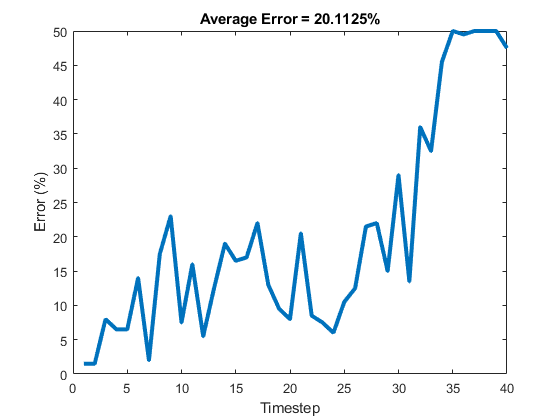

figure;
plot([nseResults.errs_nse]*100,'LineWidth',3)
xlabel('Timestep')
ylabel('Error (%)')
title("Average Error = "+mean([nseResults.errs_nse]*100)+"%")

## Plotting Of Just data, attack points, and generated data

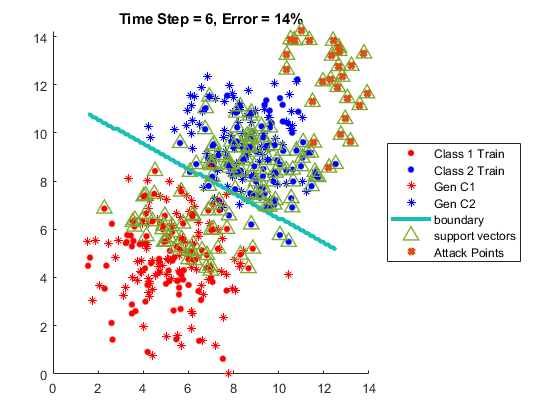

timeStep = 6;
svmMatch = true;
svmNumber = 14;
plotGenData = true;
plotResults(classInfo,genDistr,atkData,nseResults,timeStep,svmNumber,svmMatch,nseData,plotGenData)

NOTE: If svmMatch  is chekced then sweeping timeStep will also update what SVM u are showing. If its not check u can keep timeStep constant and sweep svmNumber with that slider. 

## SINDy Results 

function [] = SINDyPlot(class,timeStep,SINDyArray,SINDyData)
    figure
    hold on
    scatter(SINDyArray(timeStep-1,class).model(1:end-1,1),SINDyArray(timeStep-1,class).model(1:end-1,2),40,[0 0.4470 0.7410],'filled')
    scatter(SINDyArray(timeStep-1,class).model(end,1),SINDyArray(timeStep-1,class).model(end,2),40,[0 0.4470 0.7410],'filled','MarkerEdgeColor',[0.9290 0.6940 0.1250],'LineWidth',2)
    scatter(SINDyData(timeStep,class).mu(1:end-1,1),SINDyData(timeStep,class).mu(1:end-1,2),40,[0.6350 0.0780 0.1840],'filled')
    scatter(SINDyData(timeStep,class).mu(end,1),SINDyData(timeStep,class).mu(end,2),40,[0.6350 0.0780 0.1840],'filled','MarkerEdgeColor',[0.9290 0.6940 0.1250],'LineWidth',2)
    legend("SINDy","Relevent SINDy Pred","True","True Current Time Step","Location","bestoutside")
    SINDyArray(timeStep,2).learnedFunctions
    hold off
end

## Plotting Function

function [] = plotResults(classInfo,genDistr,atkData,nseResults,timeStep,svmNumber,svmMatch,nseData,plotGenData)

figure

hold on



gscatter(nseData(timeStep).dataTrain(:,1),nseData(timeStep).dataTrain(:,2),nseData(timeStep).labelsTrain,'rb','.')
if plotGenData == true
    gscatter(genDistr(timeStep).data(:,1),genDistr(timeStep).data(:,2),genDistr(timeStep).labels,'rb','*')
end
if svmMatch == true
    mdl = nseResults(timeStep).net.classifiers{1, timeStep}.classifier;
else
    mdl = nseResults(timeStep).net.classifiers{1, svmNumber}.classifier;
end

maxBounds = max(nseData(timeStep).dataTrain);
minBounds = min(nseData(timeStep).dataTrain);
X1 = linspace(minBounds(1),maxBounds(1));
X2 = linspace(minBounds(2),maxBounds(2));
[x1 x2] = meshgrid(X1,X2);
for i = 1:size(x1,2)
    myGrid = [x1(:,i) x2(:,i)];
    gridScores(:,i) = predict(mdl, myGrid);
end
[one,two] = contour(x1, x2, gridScores,1,'LineWidth',3);
plot(mdl.SupportVectors(:,1),mdl.SupportVectors(:,2),'^','MarkerSize',10,'Color',[0.4660 0.6740 0.1880],'LineWidth',1)
plot(atkData(timeStep).points(:,1),atkData(timeStep).points(:,2),...
    'x','Color',[0.8500 0.3250 0.0980],'LineWidth',3)
hold off
title("Time Step = " + timeStep +", Error = "+nseResults(timeStep).errs_nse*100+"%")
if plotGenData == true
        legend('Class 1 Train','Class 2 Train','Gen C1','Gen C2','boundary','support vectors','Attack Points','Location','eastoutside')
else
    legend('Class 1 Train','Class 2 Train','boundary','support vectors','Attack Points','Location','eastoutside')
end
end

## Drift Detection Function

function [drift] = checkSINDy(SINDyArray,SINDyData,StdevThresh,iTStep,iClass)
    train = SINDyArray(iTStep-1,iClass).data;
    curData = SINDyData(iTStep,iClass).mu;    
    SINDY = SINDyArray(iTStep-1,iClass).model;
    [drift, ~] = detectDrift(train, curData, SINDY, StdevThresh);
end